clear all;
clc;
ts = 0.01;          %time period
t = -1000:1000;
M = 10;             %M point value
y = zeros(1,2001);  %output


%set sn
s = 10*sin(2*pi*ts*t).*(t>=0)+0.*(t<1000);

%set dn
for i =1:2001
    d = 2*rand(1,i) - 1;
end

%set xn
for i = 1:2001
    x(1,i) = s(1,i) + d(1,i);
end

%set yn
y = zeros(1,2001);
for i = M+1:2001
    temp = 0;
    for n = 1:M
        temp = temp + x(1,i-n);
    end
    y(1,i) = temp / M;
end


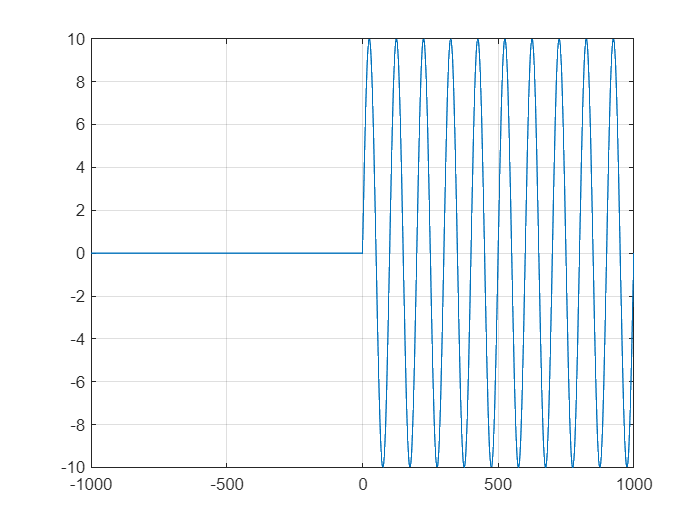

plot(t,s);grid on;

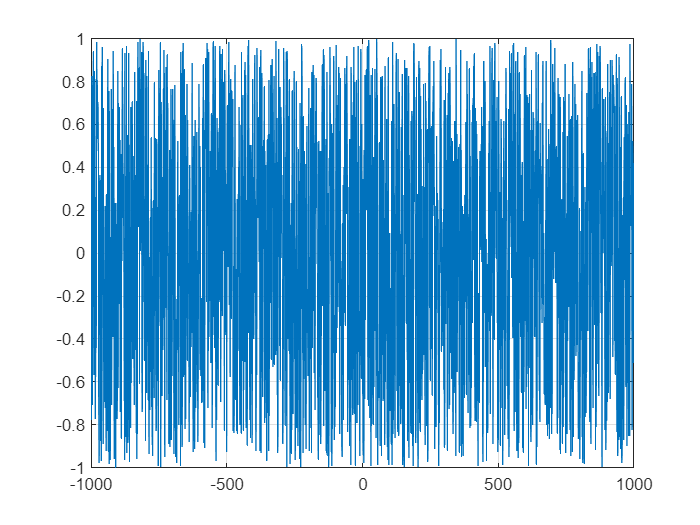

plot(t,d);grid on;

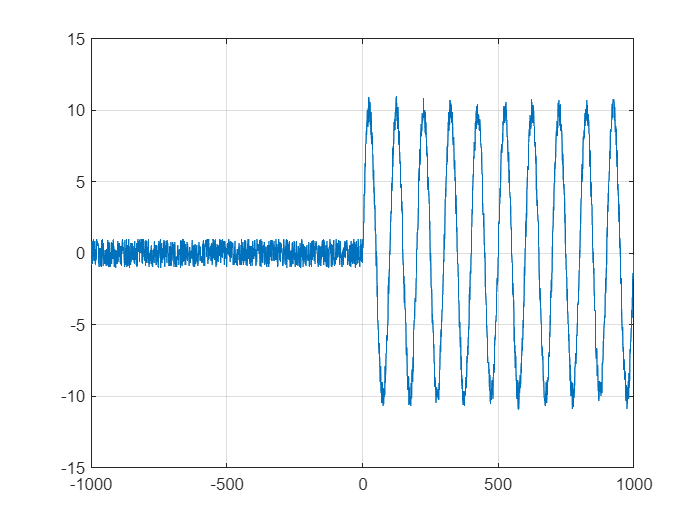

plot(t,x);grid on;

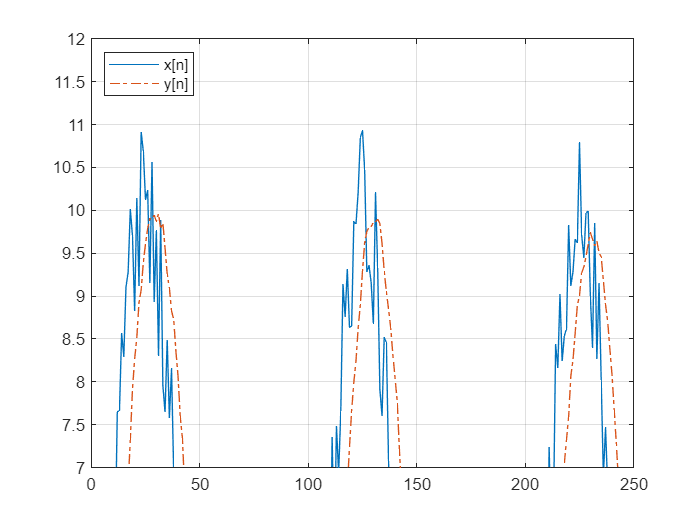

%to see the data is smooth or not
plot(t,x,'-');grid on;
hold on
plot(t,y,'-.');grid on;
xlim([0 250]);
ylim([7 12]);
legend({'x[n]','y[n]'},'Location','northwest');
hold off

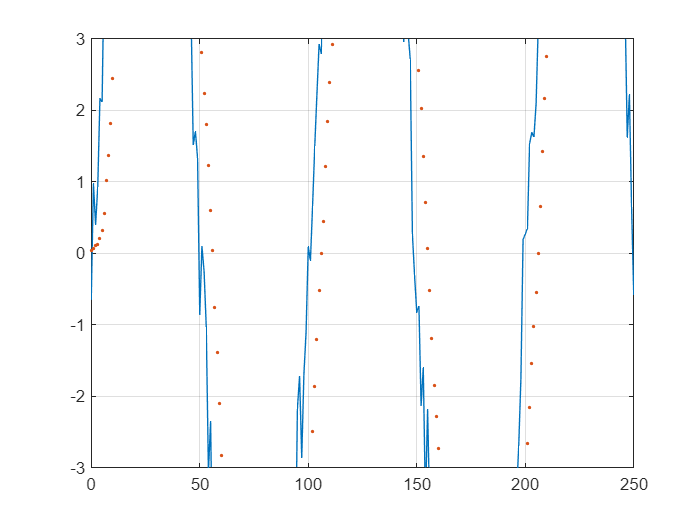

%to see the the data phase is lag or not 
plot(t,x,'-');grid on;
hold on
plot(t,y,'.');grid on;
xlim([0 250]);
ylim([-3 3]);
hold off

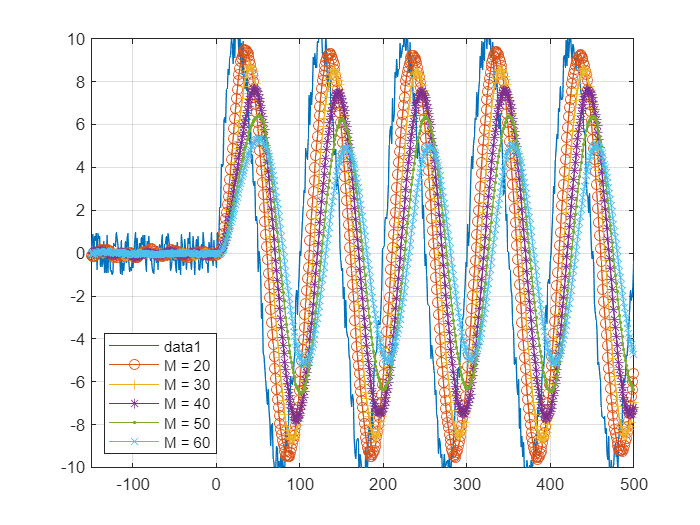

%compare different m 
y1 = zeros(1,2001);
M1 = [20,30,40,50,60];
all_marks = {'o','+','*','.','x','s','d','^','v','>','<','p','h'};

plot(t,x);grid on;hold on
for a = 1:5
    M = M1(a);
    txt = ['M = ',num2str(M)];
    for i = M+1:2001
        temp = 0;
        for n = 1:M
            temp = temp + x(1,i-n);
        end
        y(1,i) = temp / M;
    end
    plot(t,y,'LineStyle','-','DisplayName',txt,'Marker',all_marks{mod(a,13)});grid on;hold on
    xlim([-150 500]);
    ylim([-10 10]);
end
hold off
legend('location','southwest')

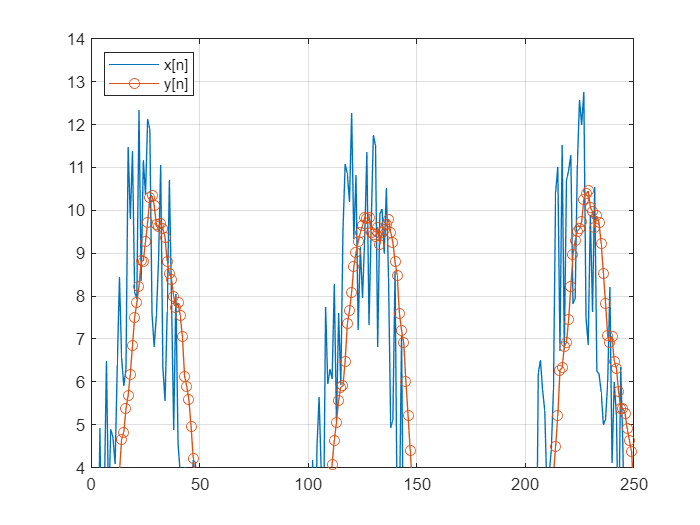

%set different dn to see the big noise will influence the data smooth

M = 10;

%set dn
for i =1:2001
    d = 6*rand(1,i) - 3;
end

%set xn
for i = 1:2001
    x(1,i) = s(1,i) + d(1,i);
end

%set yn
y = zeros(1,2001);
for i = M+1:2001
    temp = 0;
    for n = 1:M
        temp = temp + x(1,i-n);
    end
    y(1,i) = temp / M;
end

%to see the data is smooth or not
plot(t,x,'-');grid on;
hold on
plot(t,y,'-o');grid on;
xlim([0 250]);
ylim([4 14]);
legend({'x[n]','y[n]'},'Location','northwest');
hold off